# Laborator 2

## Problema 2

Să se traseze graficul funcției de probabilitate (*pdf*) și a funcției de repartiție (*cdf*) a unei variabile aleatoare $X$ care urmează legea *geometrică* de parametru $p$ (dat de utilizator).

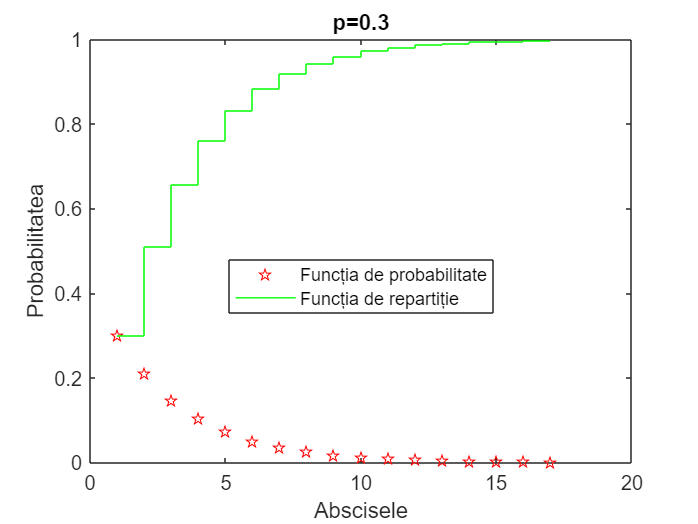

X = 0:1:16;
p = 0.3;
figure(1)
plot(geopdf(X,p),'rp')
hold on
stairs(geocdf(X, p),'g')
title('p=0.3')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

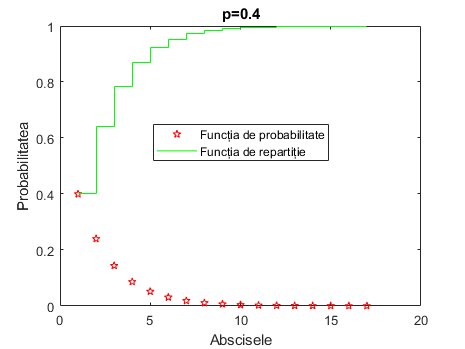

p = 0.4;
figure(2)
plot(geopdf(X,p),'rp')
hold on
stairs(geocdf(X, p),'g')
title('p=0.4')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

## Problema 3

Să se traseze graficul funcției de probabilitate (*pdf*) și a funcției de repartiție (*cdf*) a unei variabile aleatoare $X$ care urmează legea *binomială* de parametri $n,p$ (dat de utilizator).

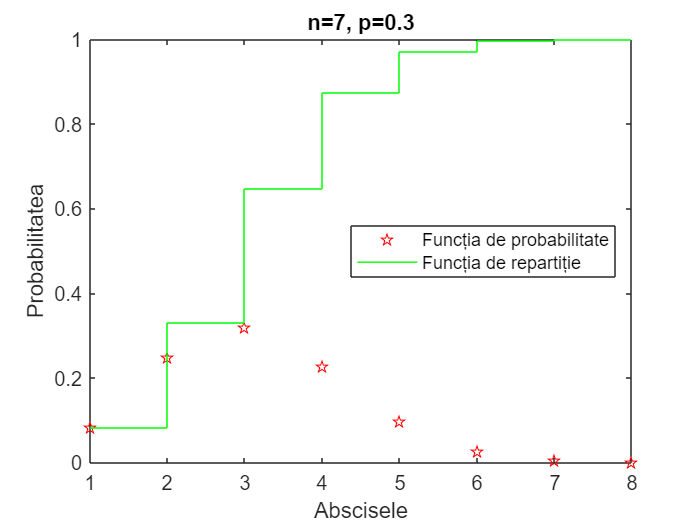

n = 7;
X = 0:1:n;
p = 0.3;
figure(1)
plot(binopdf(X,n,p),'rp')
hold on
stairs(binocdf(X,n,p),'g')
title('n=7, p=0.3')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="east")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

## Problema 4

Să se traseze graficul funcției de probabilitate (*pdf*) și a funcției de repartiție (*cdf*) a unei variabile aleatoare $X$ care urmează legea *lui Poisson* de parametru $\lambda$ (dat de utilizator).

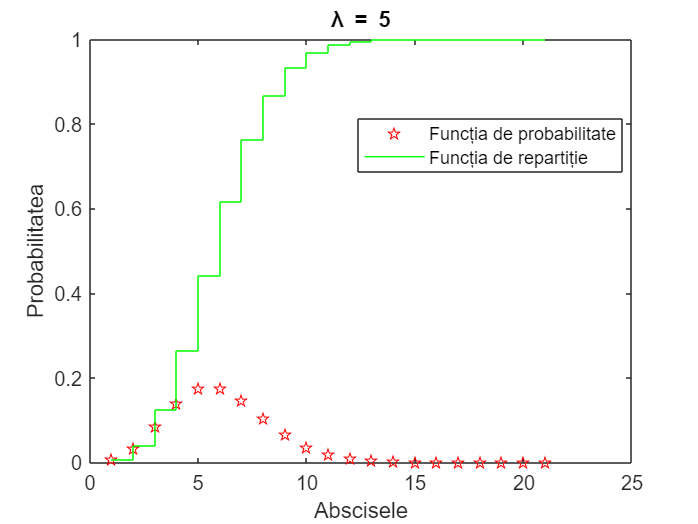

lambda = 5;
X = 0:1:4*lambda;
figure(1)
plot(poisspdf(X,lambda),'rp')
hold on
stairs(poisscdf(X,lambda),'g')
title('\lambda = 5')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

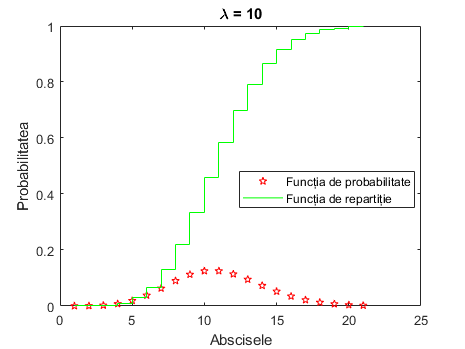


lambda = 10;
figure(2)
plot(poisspdf(X,lambda),'rp')
hold on
stairs(poisscdf(X,lambda),'g')
title('\lambda = 10')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

## Problema 5

Să se traseze graficul funcției de probabilitate (*pdf*) și a funcției de repartiție (*cdf*) a unei variabile aleatoare $X$ care urmează legea *Student (T)* de parametru $n$ (dat de utilizator). Să se folosească „regula celor 3$\sigma$”.

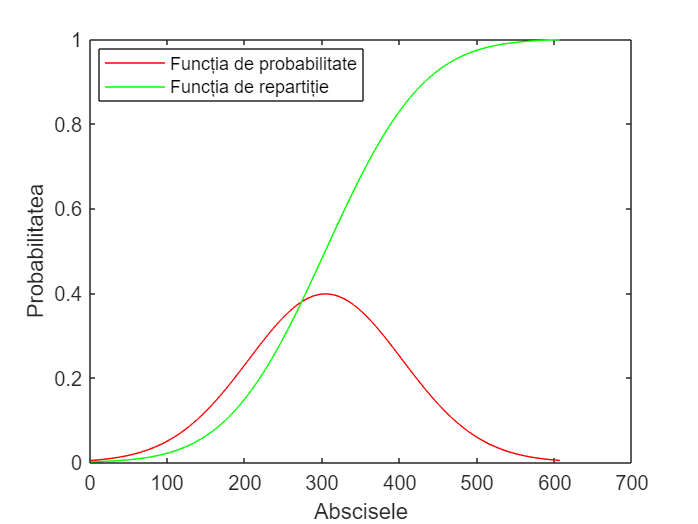

n=100;
[m, s] = tstat(n);
X = m-3*sqrt(s):0.01:m+3*sqrt(s);
figure(1)
plot(tpdf(X,n),'r')
hold on
plot(tcdf(X,n),'g')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

## Problema 6

Să se traseze graficul funcției de probabilitate (*pdf*) și a funcției de repartiție (*cdf*) a unei variabile aleatoare $X$ care urmează legea *normală* de parametri $m,\sigma$ (dat de utilizator).

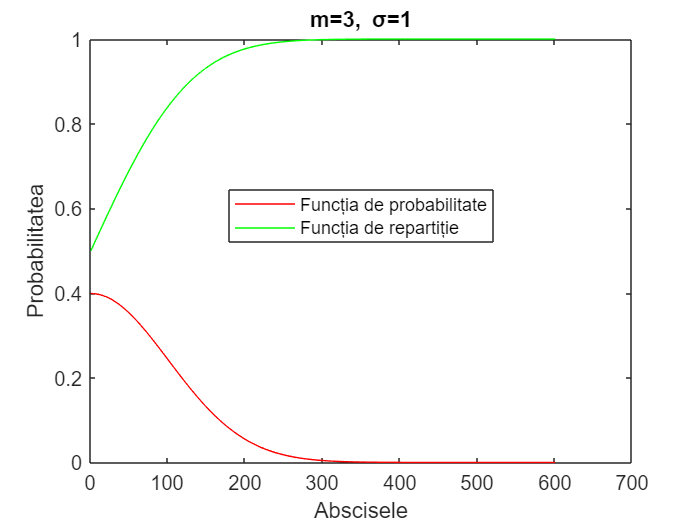

m = 3;
s = 1;
X = m-3*sqrt(s):0.01:m+3*sqrt(s);
figure(1)
plot(normpdf(X),'r')
hold on
plot(normcdf(X),'g')
title('m=3, \sigma=1')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

## Problema 7

Să se traseze graficul funcției de probabilitate (*pdf*) și a funcției de repartiție (*cdf*) a unei variabile aleatoare $X$ care urmează legea *exponențială* de parametru $\lambda$ (dat de utilizator).

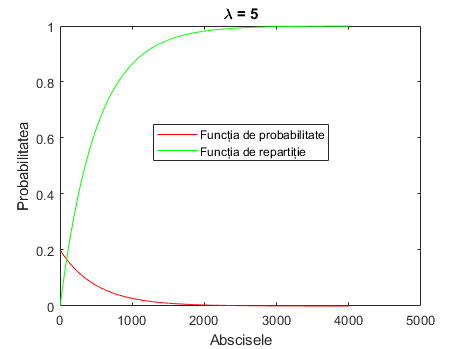

[m,s]=expstat(lambda);
X = max(0,m-3*sqrt(s)) : 0.01 :m+ 3*sqrt(s);
lambda = 5;
figure(1)
plot(exppdf(X,lambda),'r')
hold on
plot(expcdf(X,lambda),'g')
title('\lambda = 5')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off

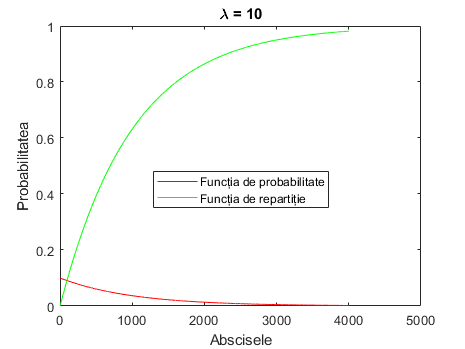


lambda = 10;
figure(2)
plot(exppdf(X,lambda),'r')
hold on
plot(expcdf(X,lambda),'g')
title('\lambda = 10')
legend('Funcția de probabilitate', 'Funcția de repartiție', Location="best")
xlabel('Abscisele')
ylabel('Probabilitatea')
hold off